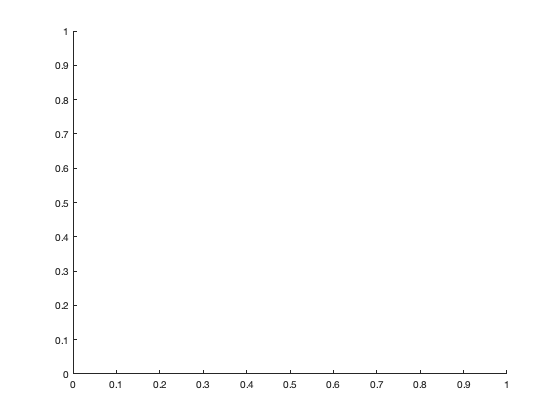

clear all
clf
hold off

% read images
mt=2; % how many compasrions with Ag
F1='water001.tif';
F2='water002.tif';

A=double(imread(F1));

A0=A(:,:,2);
V=size(A0);
A0=A0(V(1):-1:1,:); % reverse order of the element
% calculation parameters
nx=1; % how many sensing elements in x
ny=5; % how many sensing elements in y

g=[52,33]; % initial points (x,y)
s=20; % sensing element size
dy=118; % period in y
dx=15; % period in x 

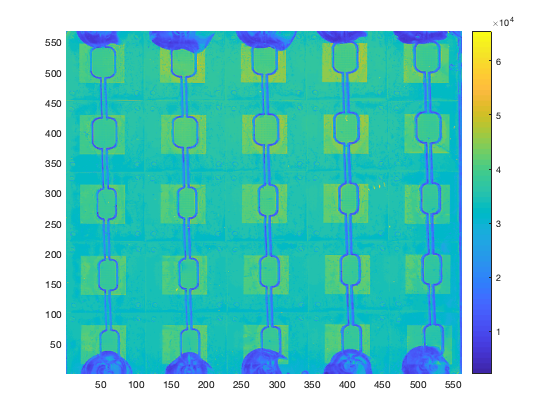

kk=0;
for mm=1:mt
    
S=eval(['double(imread(F',num2str(mm),'))']);
    
R=S(V(1):-1:1,:,1);
G=S(V(1):-1:1,:,2);
B=S(V(1):-1:1,:,3);

%Z=R;
Z=(G-R)./(G+R);

figure(1),pcolor(A0);shading flat;colorbar;
hold on

figure(2),pcolor(A0);shading flat;colorbar;
hold on

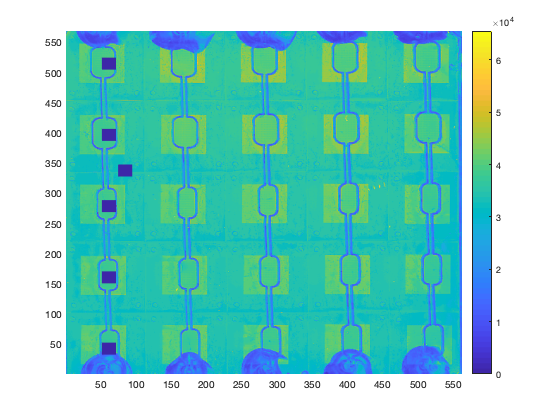


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Analysis

kk=kk+1;
ll=0;
for n=0:ny-1
    yy=round(g(2)+n*dy:g(2)+n*dy+s);
    for m=0:nx-1
    xx=round(g(1)+m*dx:g(1)+m*dx+s); 
    H=Z(yy,xx);
   ll=ll+1;
    me(kk,ll)=mean(mean(H));
    sd(kk,ll)=std(std(H));
    
   figure(1),pcolor(xx,yy,H);shading flat;colorbar;
   hold on
   figure(2),text(xx(1),yy(1),num2str(ll));
    hold on
    
    end
  end
   
    yy=round(g(2)+2*dy+dy/2:g(2)+2*dy+dy/2+s);
    xx=round(g(1)+1*dx+dx/2:g(1)+1*dx+dx/2+s); 
    H=Z(yy,xx);
   
   figure(1),pcolor(xx,yy,H);shading flat;colorbar;
   hold off

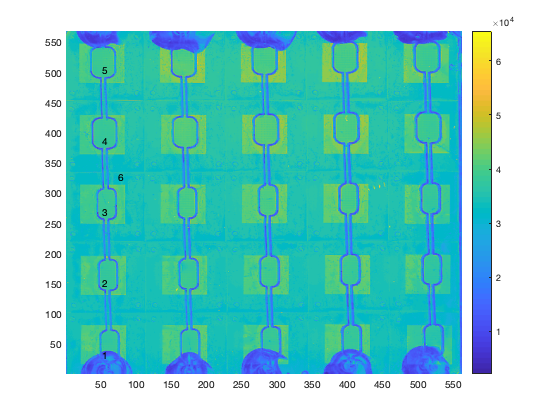

   figure(2),text(xx(1),yy(1),num2str(ll+1));
    hold off

Error using matlab.graphics.primitive.Text/horzcat
Conversion to matlab.graphics.primitive.Text from char is not possible.

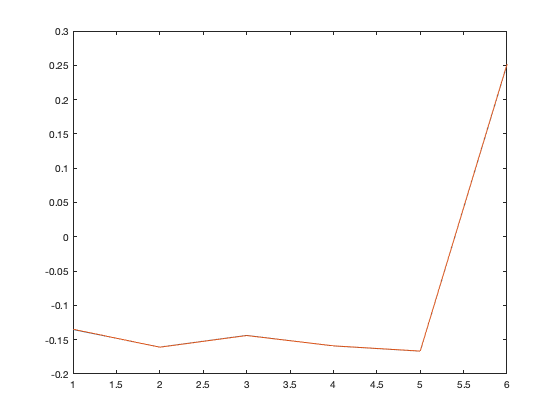

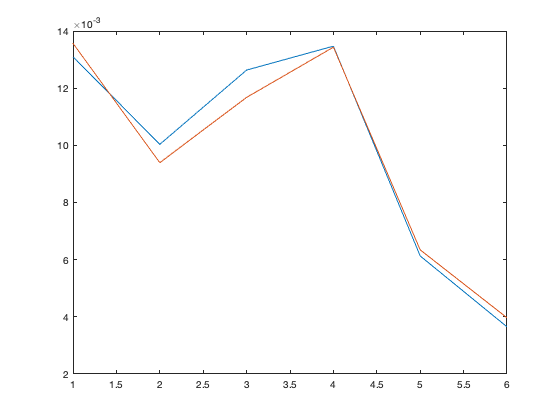

   %pause(0.5);
   
    me(kk,ll+1)=mean(mean(H));
    sd(kk,ll+1)=std(std(H));
    
    if mm>1
    mb(kk-1,:)=me(kk,:)-me(kk-1,:);
    end
          
end %end mt

figure(3)    
plot(1:nx*ny+1,me)
figure(4)    
plot(1:nx*ny+1,sd)

figure(5)    
plot(1:nx*ny+1,mb)



Rs=[me;mb;sd]';
eval(['save ',gname, '.dat Rs -ascii']);